detector = load("Detector.mat")

detector = struct with fields:
    detector: [1×1 yolov2ObjectDetector]


det  = detector.detector

det =   yolov2ObjectDetector with properties:

            ModelName: 'can'
              Network: [1×1 DAGNetwork]
    TrainingImageSize: [416 416]
          AnchorBoxes: [4×2 double]
           ClassNames: [can    bottle    pouch]


img = imread("ss.png");

[bboxes,scores,labels] = detect(det, img)

bboxes =    472     1   126   105
   330    32   112   114
   140    61   105   135
   957   257   215   239
   549   413   239   177
   492   417   215   195


scores = 6×1 single column vector
    0.6867
    0.5008
    0.9362
    0.5597
    0.7875
    0.8403


labels = 6×1 categorical array
     pouch 
     pouch 
     pouch 
     bottle 
     can 
     can 


need = bboxes(labels=='pouch',:);
need

need =    472     1   126   105
   330    32   112   114
   140    61   105   135


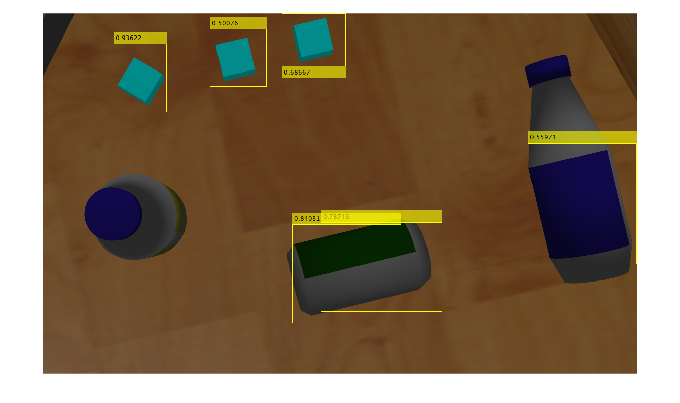


if(~isempty(bboxes))
    img = insertObjectAnnotation(img,'rectangle',bboxes,scores);
end
figure
imshow(img)